# GLCM

The notes and code was taken from FIT3081 Week 11 P2.

The gray-level co-occurrence matrix can reveal certain properties about the spatial distribution of the gray levels in the texture image. 

Contrast: Measures the local variations in the GLCM 

Correlation: Measures the joint probability occurrence of the specified pixel pairs 

Energy: Provides the sum of squared elements in the GLCM. Also known as uniformity or the angular second moment. 

Homogeneity: Measures the closeness of the distribution of elements in the GLCM to the GLCM diagonal. 

Entropy: Indicates degree of disorder or non-homogeneity. 

Sample of how the results would look like:

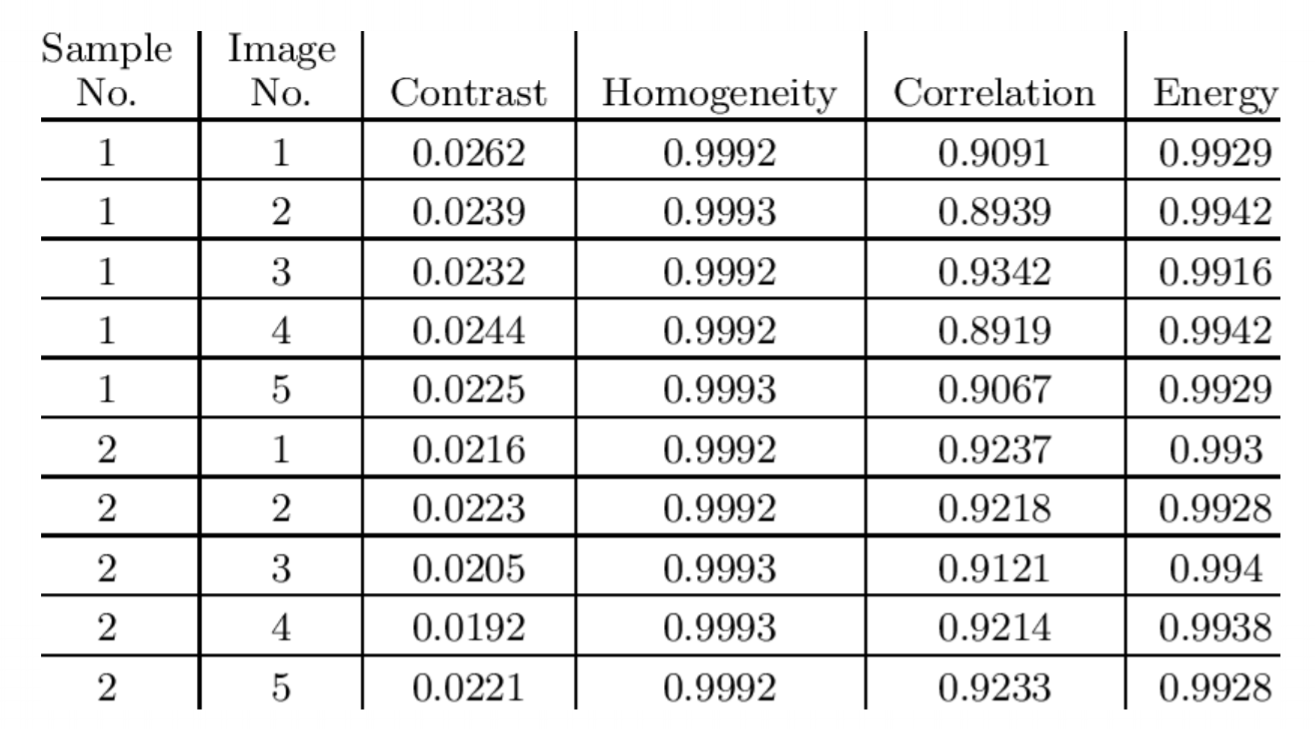

Below is the code for GLCM

I = imread('coins.png');
[GLCM, SI] = graycomatrix(I,'Offset',[1 1],'NumLevels',8,'GrayLimits',[],'Symmetric', true);
stats = graycoprops(GLCM,'all');
disp(GLCM);

        2148        1148         107         116          96          22           0           0
        1148       92340         500         317         316         104           0           0
         107         500         310         285         254         291          11           0
         116         317         285        1444         566         401          59           0
          96         316         254         566        4184        2476         215          21
          22         104         291         401        2476       17604        2598         148
           0           0          11          59         215        2598        4862         897
           0           0           0           0          21         148         897        1722



disp(stats);

       Contrast: 0.3466
    Correlation: 0.9544
         Energy: 0.4156
    Homogeneity: 0.9183



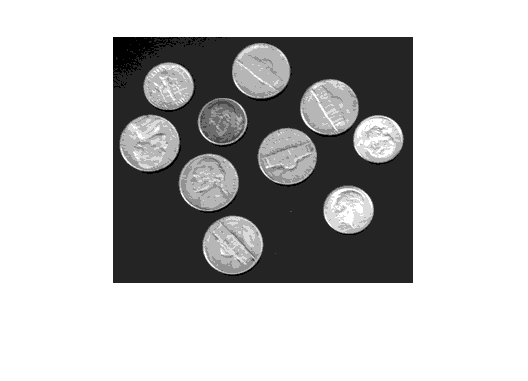

figure, imshow(SI,[]);

[GLCM1,SI1] = graycomatrix(I,'Offset',[2 0;0 2]);
stats1 = graycoprops(GLCM1,'all');
disp(GLCM1);


(:,:,1) =

           0          33          49           0           0           0           0           0
           0       14705        1953         118         103          83          25           5
           0        1001       30622         215         217         248         111          19
           4         147         111         627         263         204          88          11
          28         176         101         287         904        1090         260          73
          50         254         123         152        1188        8198        1924         210
           0          60          36          31         191        2051        2696         586
           0          16          38          25          53         225         547         665


(:,:,2) =

          20          61           1           0           0           0           0           0
          37       15071        1492          98          72          65          23          18
     

disp(stats1);

       Contrast: [0.5623 0.5070]
    Correlation: [0.9081 0.9171]
         Energy: [0.2327 0.2378]
    Homogeneity: [0.8885 0.9001]



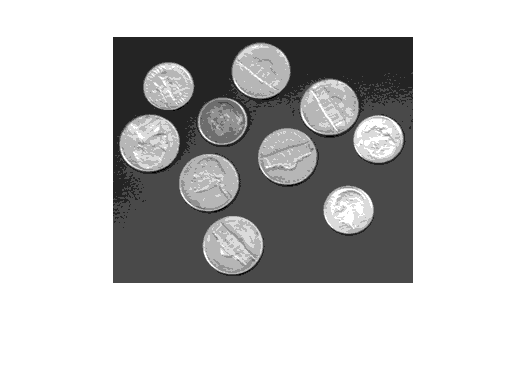

figure, imshow(SI1,[]);